# Event and Anti-event (binary)

18 pairs comparison of events, antievents and second round event selection.

#### Plot first and second round event & antievent frequency on time line 

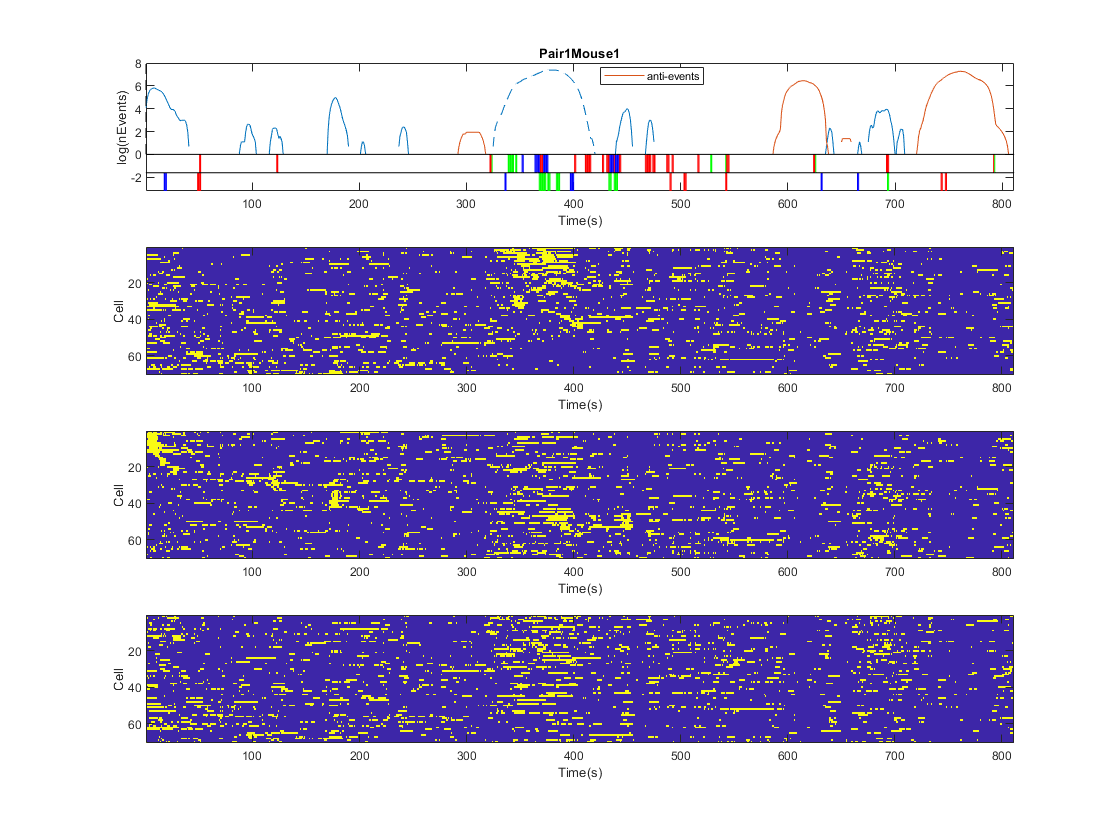

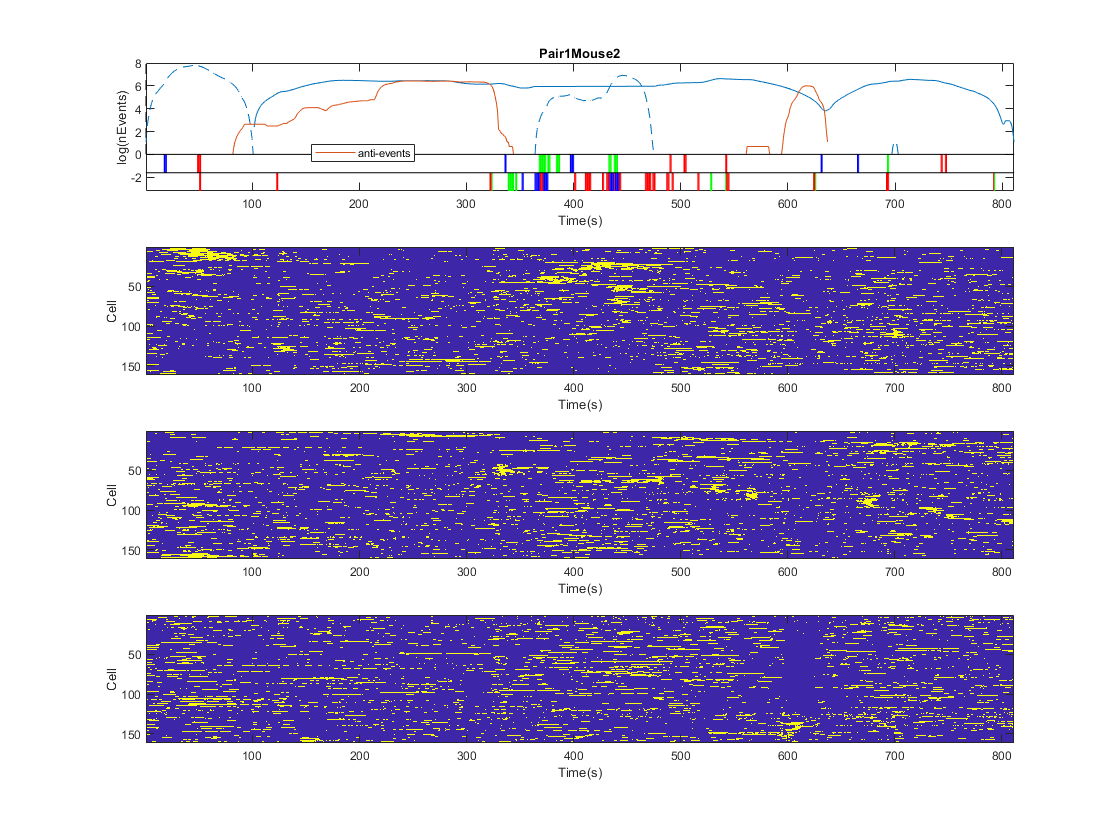

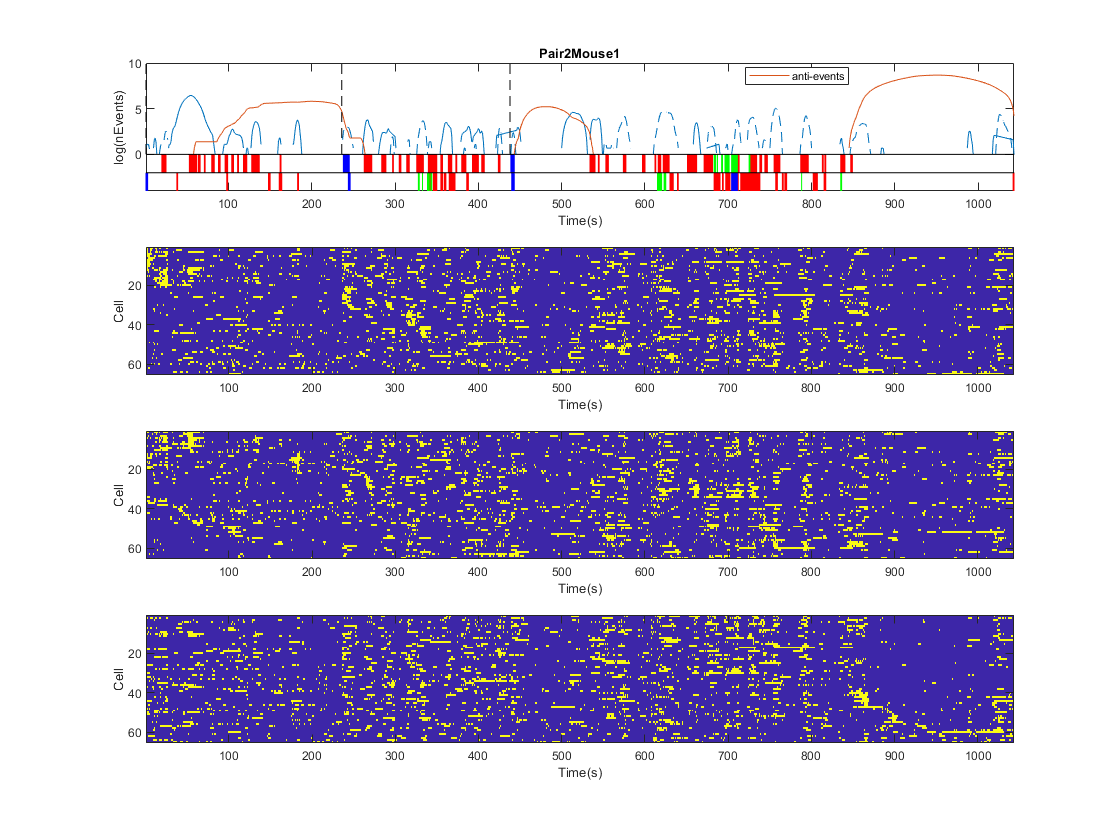

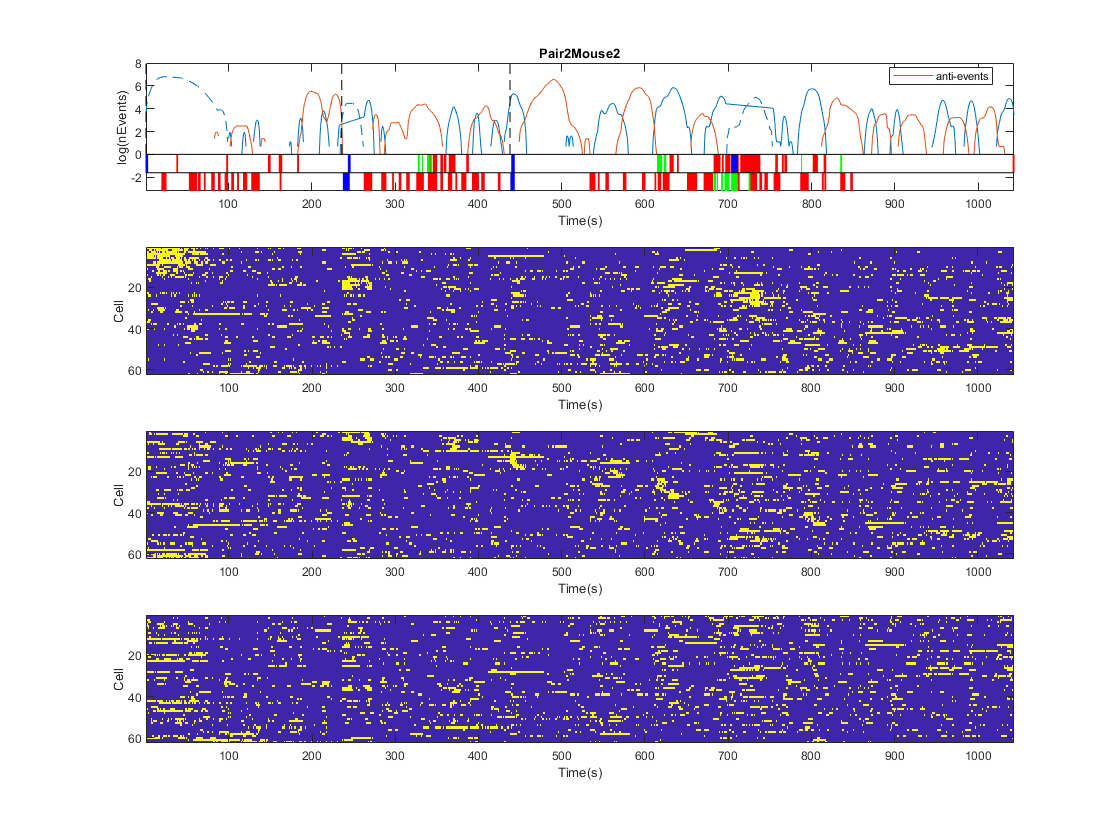

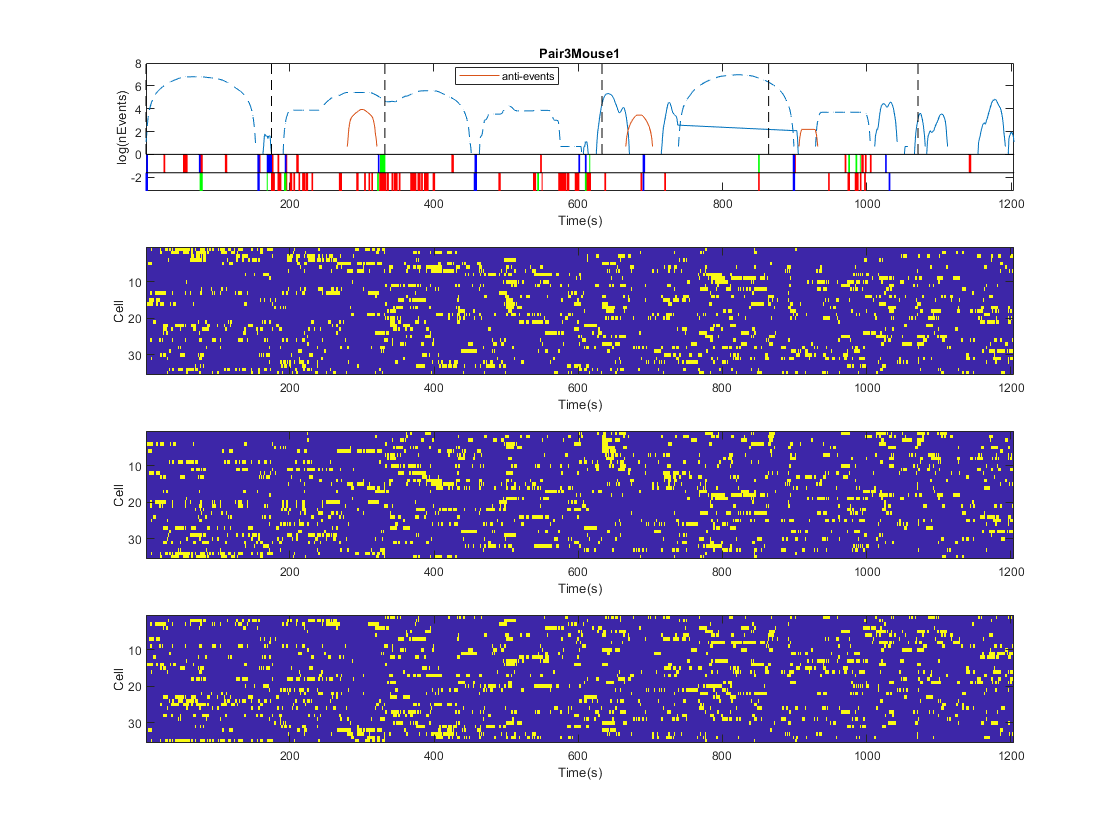

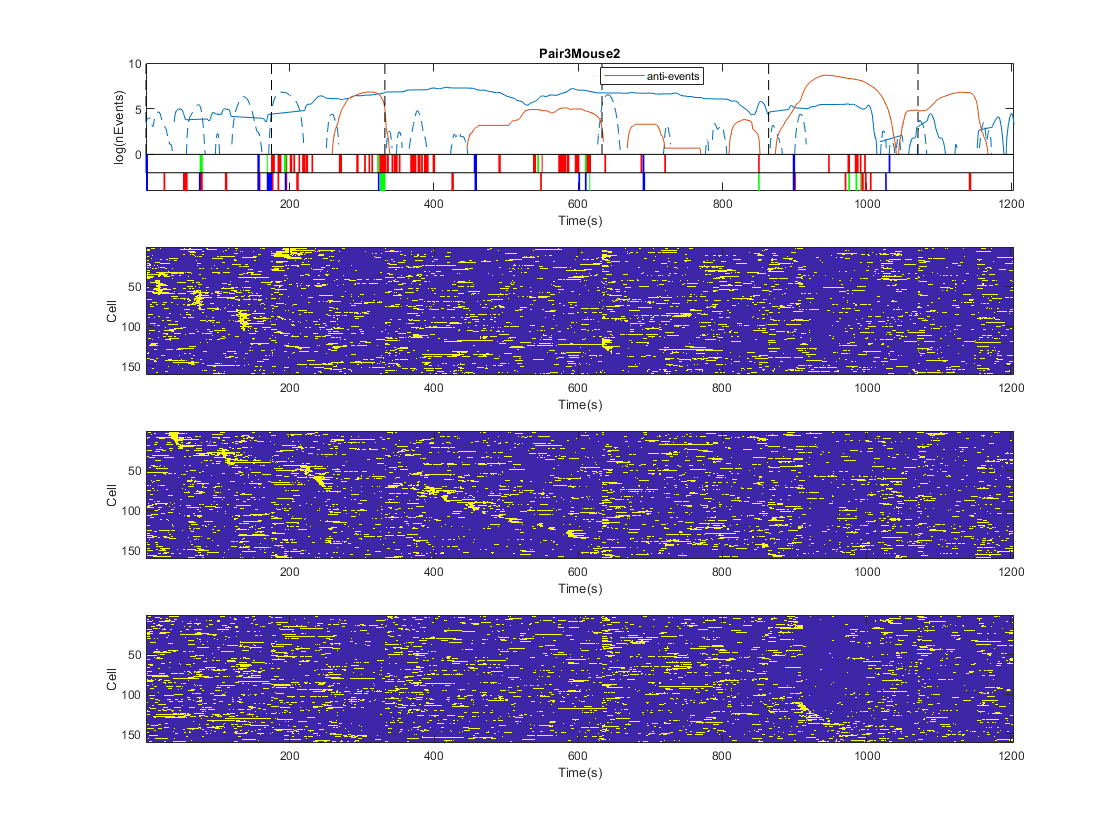

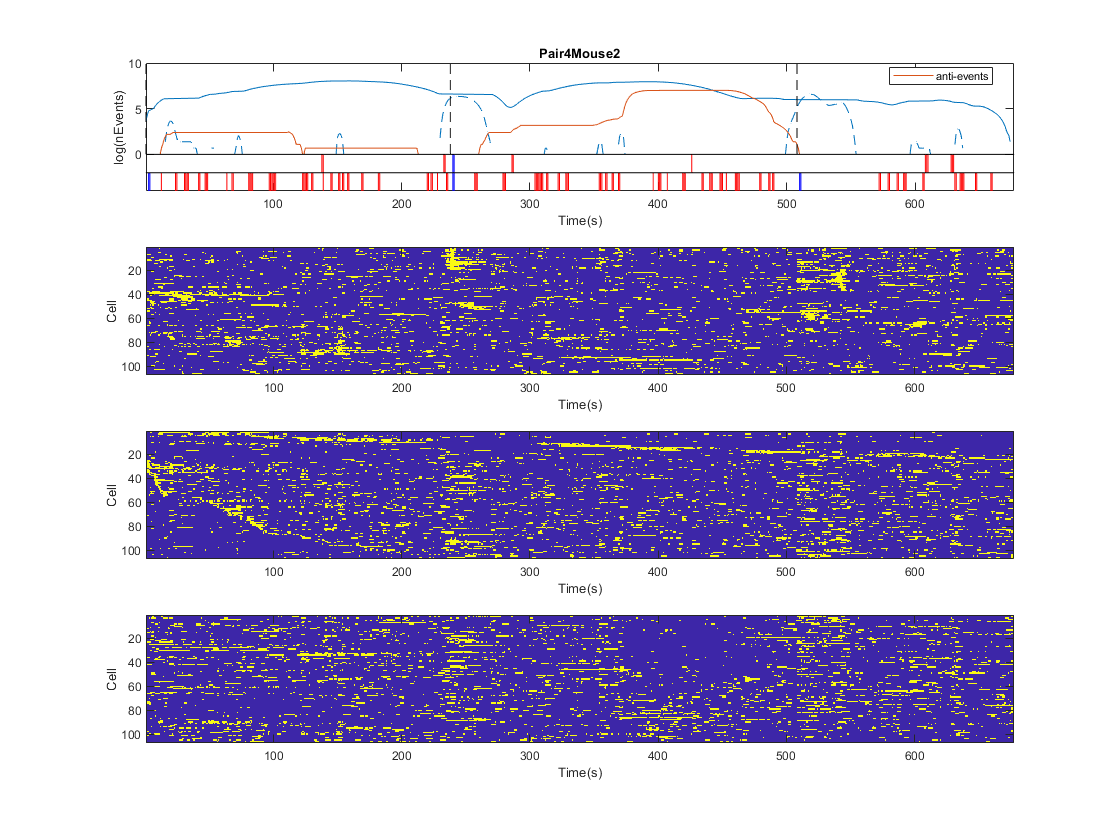

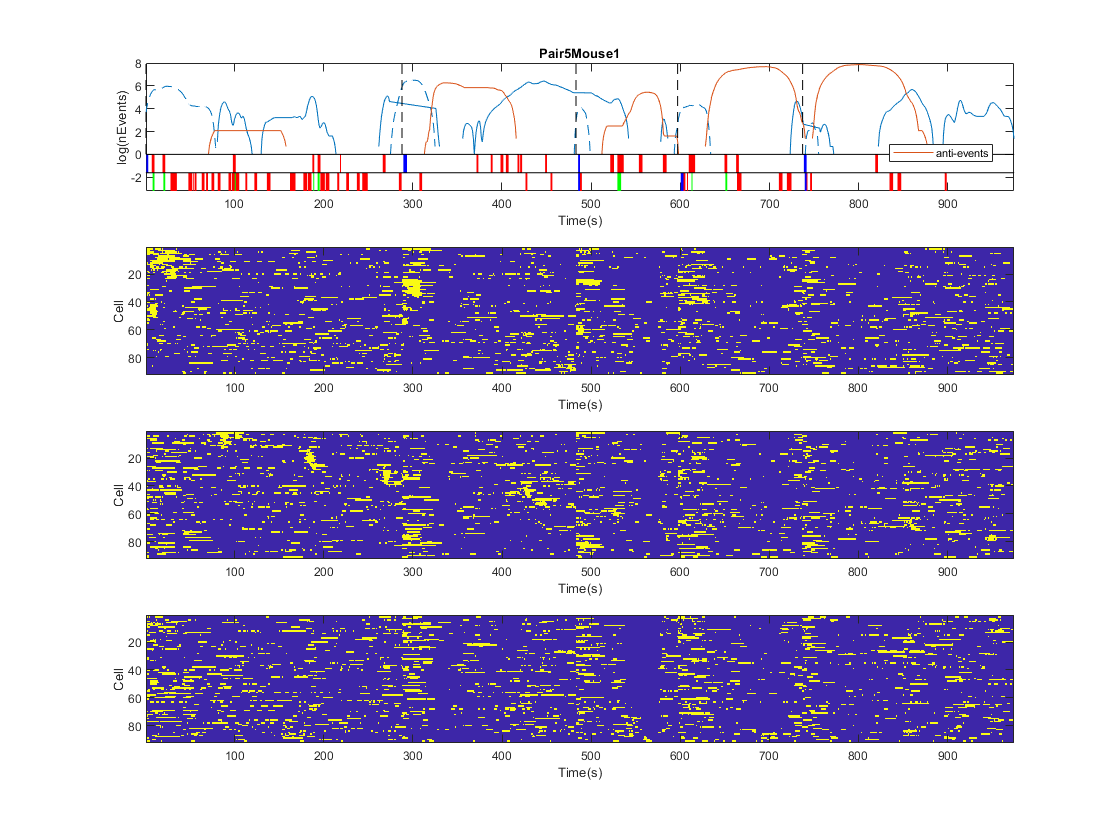

load('em_18p_antievent_binary_0.05.mat')
load('em_18p_binary_th0.5.mat')
load('dTT_SYN_18Pair_R3_10032020.mat')
ca_cl=em{1,1}.ca_cl;
close all
% plot first and second round events
N=18; % 18 pairs
th=1;
x=0;
for p=1:N % pair index
    for m=1:2
        ons=E{p}{m}.BehaviorVectors(:,end); % trial onset 
        beh=E{p}{m}.BehaviorVectors(:,1:3); % self behaviour 
        opbeh=E{p}{setdiff([1 2],m)}.BehaviorVectors(:,1:3); % opponent behaviours
        em1=em{1,1}.ne{p,m}';em2=em{2,1}.ne{p,m}';em2filter=em{2,1}.timefilter{p,m};antieve=anti{1,1}.ne{p,m}';
        x=x+1;f1=figure(x);f1.Position(3)=2*f1.Position(3);f1.Position(4)=2*f1.Position(4);
        subplot(4,1,1)
        eventplot_tt(em1,em2,em2filter,antieve,ons,beh,opbeh,"trial",true,"logscale",true);
        title(sprintf('Pair%dMouse%d',p,m))
        subplot(4,1,2) % raster plot according to first round event 
        nc=size(em{1,th}.eve{p,m},1);
        c=reorder_ca(em{1,th}.cells{p,m},nc);
        imagesc(ca_cl{p,m}(c,:));xlabel('Time(s)');ylabel('Cell');
        subplot(4,1,3) % raster plot according to second round event 
        c=reorder_ca(em{2,th}.cells{p,m},nc);
        imagesc(ca_cl{p,m}(c,:));xlabel('Time(s)');ylabel('Cell');
        subplot(4,1,4) % raster plot according to anti event 
        c=reorder_ca(anti{1,th}.cells{p,m},nc);
        imagesc(ca_cl{p,m}(c,:));xlabel('Time(s)');ylabel('Cell');
    end
end              % 3 rasters were ordered according to 1st round event, 2nd round event & anti-event, respectively